# Next Paper, Journal?

### TO DO

- ensure output variable names from true system and digitial twin match (except for the filters)

- degradation parameter std should start off large and then update based on the true system filters

- parallelize digitaltwin execution, gather total flight times, create distribution. this is RUL for next true system flight

### Load paths and variables

addpath(genpath(pwd));
load_fresh_workspace;
load_trajectory;
%init_simulation_params;

### Simulate

Mode Selection 

- true system - nominal

- true system - degraded

- digital twin - nominal

- digital twin - degraded

%sys = "TrueSystem";
sys = "DigitalTwin";

mode = "Nominal";
%mode = "Degraded";
degraded_level = 11;

Degraded or Nominal

if mode == "Degraded"
    battery.R0=rdeg(degraded_level);
    battery.Q=qdeg(degraded_level);
    Motor2.Req=mdeg(degraded_level);
    Motor4.Req=mdeg(degraded_level);
else
    battery.R0=rdeg(1);
    battery.Q=qdeg(1);
    Motor2.Req=mdeg(1);
    Motor4.Req=mdeg(1);
end

if sys == 'TrueSystem'
    octomodel.sampletime = .025;
    load_system('truesystem');
    tic
    sim('truesystem.slx');
    toc
else
    batterytwin = battery;
    Motortwin2 = Motor2;
    Motortwin4 = Motor4;
    octomodel.sampletime = .05;
    load_system('digitaltwin1c');
    tic
    sim('digitaltwin1c.slx');
    toc
end

Elapsed time is 163.115091 seconds.


## Plot Path

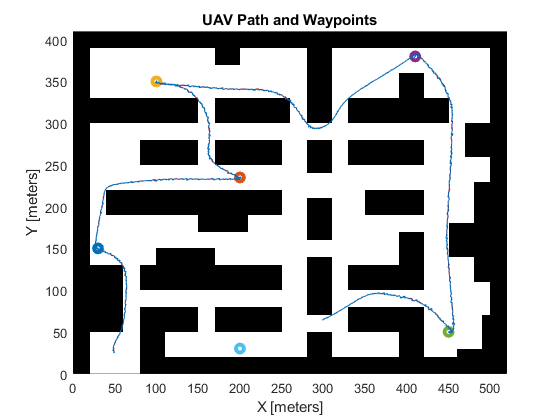

f1 = figure(1); clf;
hold on;
show(map);

for i = 1:length(waypoints)
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3); 
end
plot(pos_actual.Data(:,1), pos_actual.Data(:,2));
plot(pos_observed.Data(:,1), pos_observed.Data(:,2));
hold off;
title("UAV Path and Waypoints");

## Euclidean Position Error

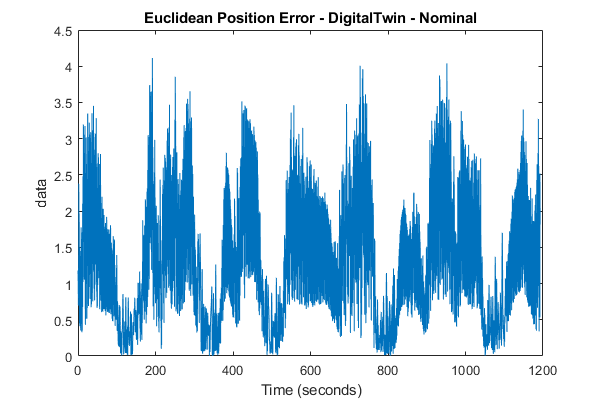

f2 = figure(2); clf;
plot(euclidean_pos_err);
ttl = sprintf("%s - %s - %s", plot1title, sys, mode);
title(ttl);

## Voltage and SOC Plot

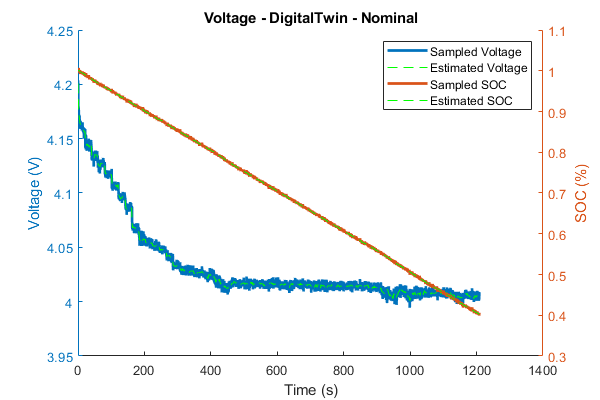

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
yyaxis left;
hold on;
plot(battery_observed.Time(:), battery_observed.Data(:,1), 'linewidth', 2, "DisplayName", "Sampled Voltage");
plot(battery_observed.Time(:), smoothdata(battery_observed.Data(:,1), 'rlowess', 20), 'g--', "DisplayName", "Estimated Voltage");
hold off;
ylabel("Voltage (V)");
yyaxis right;
hold on;
plot(battery_observed.Time(:), battery_observed.Data(:,2), 'linewidth', 2, "DisplayName", "Sampled SOC");
plot(battery_observed.Time(:), smoothdata(battery_observed.Data(:,2), 'rlowess', 20), 'g--', "DisplayName", "Estimated SOC");
hold off;
ttl = sprintf("%s - %s - %s", plot5title, sys, mode);
title(ttl);
xlabel("Time (s)");
ylabel("SOC (%)");
legend();

## Current Plot

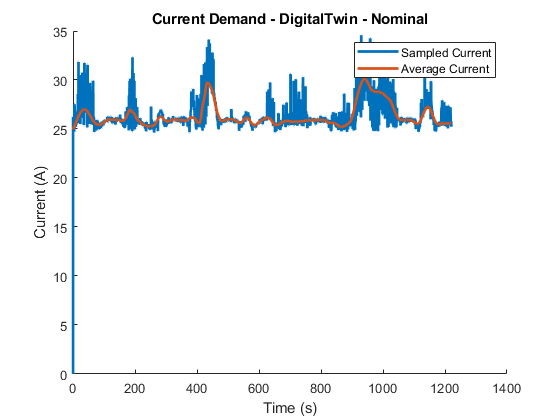

f2 = figure(2); clf;
f2.Position = [0 0 600 400];
hold on;
plot(downsample(current_observed.Time(:,1), 2),downsample(co(:,1), 2), 'linewidth', 2, "DisplayName", "Sampled Current");
plot(downsample(current_observed.Time(:,1), 2),smoothdata(downsample(co(:,1), 2), 'rlowess', 100), 'linewidth', 2, "DisplayName", "Average Current");
ttl = sprintf("%s - %s - %s", plot4title, sys, mode);
title(ttl);
xlabel("Time (s)");
ylabel("Current (A)");
legend();

# *********************************************************************************************************************

# Scratch paper below

# *********************************************************************************************************************

sprintf("time: %fs\tmission: %d\tarrived: %d\ttrue_z: %f\ttwin_z: %f\ttwin_I: %f", t2, i, twin_res(i,1), ending_soc_true(i), ending_soc_twin(i), currents_twin(i))
     sprintf("\t\t[TRUE]R0: %f\tQ: %f\tRM: %f\ttracking: %d\tlowbatt: %d", battery.R0, battery.Q, Motor2.Req, trackingerror.Data(end,1), lowsoc.Data(end,1))
     sprintf("\t\t[TWIN]R0: %f\tQ: %f\tRM: %f\ttracking: %d\tlowbatt: %d", batterytwin.R0, batterytwin.Q, Motortwin2.Req, trackingerror.Data(end,1), lowsoc.Data(end,1))
     sprintf("\t\t[TWIN] pos_errs: %.2f,%.2f,%.2f\ttrack_errs: %d, %d", pos_errs_twin(i,1), pos_errs_twin(i,2), pos_errs_twin(i,3), track_err_twin(i,1), track_err_twin(i,2))
     sprintf("\t\t[TRUE] pos_errs: %.2f,%.2f,%.2f\ttrack_errs: %d, %d", pos_errs_true(i,1), pos_errs_true(i,2), pos_errs_true(i,3), track_err_true(i,1), track_err_true(i,2))


sprintf("time: %fs\tmission: %d\tarrived: %d\ttrue_z: %f\ttwin_z: %f\ttwin_I: %f", t2, i, twin_res(i,1), ending_soc_true(i), ending_soc_twin(i), currents_twin(i))
     sprintf("\t\tR0: %f\tQ: %f\tRM: %f\tpos_err: %.2f,%.2f", battery.R0, battery.Q, Motor2.Req, pos_err_x, pos_err_y)

set_param('truesystem','FastRestart','off');
set_param('digitaltwin','FastRestart','off');

## show map with reference and resulting trajectory

2 D comparison

timeest=estimations.Time;
estimatedpos=estimations.Data;
figure1 = figure;
hold on;
scatter(XrefTot(:,2),YrefTot(:,2));
scatter(estimatedpos(:,1),estimatedpos(:,2));

clf; plot(pos.Data(:,1), pos.Data(:,2));


% trajectory error
% figure12 = figure;
% hold on;
% xerror=XrefTot(:,2)-estimatedpos(1:end-(length(estimatedpos(:,1))-length(XrefTot(:,2))),1);
% yerror=YrefTot(:,2)-estimatedpos(1:end-(length(estimatedpos(:,1))-length(XrefTot(:,2))),2);
% plot(xerror);
% plot(yerror);

% single variable comparison
figure13 = figure;
timev=reals.Time;
variables=reals.Data;
timeest=estimations.Time;
estimated=estimations.Data;
matrices=bounds.Data(:,:,:);
limits=[];
for i=1:length(matrices)
    limits(:,i)=3*sqrt(diag(matrices(:,:,i)));
end
subplot(2,1,1);
plot(timev,variables(:,1),'k');
hold on;
plot(timev,estimated(:,1),'r');
plot(timev,estimated(:,1)+limits(1,:)','b-');
plot(timev,estimated(:,1)-limits(1,:)','b-');

## show soc and voltage across the trajectory

timevol=voltage.Time;
estimatedvol=voltage.Data;
timesoc=soc
estimatedsoc=soc.Data;
figure2 = figure;
plot(timevol,estimatedvol(:,3));
figure3 = figure;
plot(timesoc,estimatedsoc(:,2));

plot(pos_errs_true(:,1), pos_errs_true(:,2))

ending_soc_true = zeros(n_missions,1);
ending_soc_twin = ending_soc_true;
currents_twin = ending_soc_twin;
currents_true = ending_soc_true;

pos_errs_true = zeros(n_missions, 3);
pos_errs_twin = pos_errs_true;

track_err_true = zeros(n_missions,2);
track_err_twin = track_err_true;

true_res = zeros(n_missions, 4);
twin_res = zeros(n_missions, 4);

twin_res(i,1) = any(arrivedprediction.Data(:,1) == 1);
twin_res(i,2) = any(lowsoc.Data(:,1) == 1);
twin_res(i,3) = any(trajectory_violation.Data(:,2) == 1);
twin_res(i,4) = any(trackingerror.Data(:,1) == 1);

track_err_x = max(track_cnt.Data(:,2));
track_err_y = max(track_cnt.Data(:,3));

pos_errs_twin(i,:) = [max(abs_pos_err.Data(:,1)) max(abs_pos_mag.Data(:,1)) max(abs_pos_mag.Data(:,2))];

track_err_twin(i,:) = [track_err_x, track_err_y];

currents_twin(i) = current_total;


true_res(i,1) = any(arrivedprediction.Data(:,1) == 1);
true_res(i,2) = any(lowsoc.Data(:,1) == 1);
true_res(i,3) = any(trajectory_violation.Data(:,2) == 1);
true_res(i,4) = any(trackingerror.Data(:,1) == 1);

track_err_x = max(track_cnt.Data(:,2));
track_err_y = max(track_cnt.Data(:,3));

pos_errs_true(i,:) = [max(abs_pos_err.Data(:,1)) max(abs_pos_mag.Data(:,1)) max(abs_pos_mag.Data(:,2))];

current_total = trapz(current.Time(:),current.Data(:,1))/3600;    

track_err_true(i,:) = [track_err_x, track_err_y];

currents_true(i) = current_total;

   % if low soc, trajectory violation, or tracking error occur
% only report failure if it didnt arrive
if any(any(true_res(:,2:end) == 1) == 1) && true_res(i,1) == 0
    missionfailure = true
    sprintf('true system mission failure on %d', i)
end

% if we didn't arrive but no fail flags were thrown
if true_res(i,1) == 0
    sprintf('true system failed to arrive on %d', i)
end

disp(true_res)
%disp(twin_res)



f2 = figure(2); clf;
hold on;
plot(abs_pos_mag.Data(:,1), 'DisplayName', '|x_{err}|');
plot(abs_pos_mag.Data(:,2), 'DisplayName', '|y_{err}|');
hold off;
legend();
ttl = sprintf("%s - %s - %s", plot2title, sys, mode);
title(ttl);
saveas(f2, sprintf("%s.png",ttl))

max(abs_pos_err)
sprintf("track errors: %d,%d,%d", track_cnt.Data(end,1), track_cnt.Data(end,2), track_cnt.Data(end,3))
sprintf("trajectory violation: %d,%d", trajectory_violation.Data(end,1), trajectory_violation.Data(end,2))
sprintf("trackingerror: %d", any(trackingerror.Data(:,1) ==1))
sprintf("arrived? %d", any(arrivedprediction.Data(:,1) == 1))
sprintf("remaining SOC: %f", batterypredictions.Data(end,2))
%sprintf("pos_err: %.2f,%.2f", pos_err.Data(end,1), pos_err.Data(end,2))


% %legend([to_dst, to_srt]);
% ttl = sprintf("%s - %s - %s", plot3, sys, mode);
% title(ttl);

%saveas(f3, sprintf("%s.png",ttl))
f4 = figure(4); clf;
plot(current);
ttl = sprintf("%s - %s - %s", plot4title, sys, mode);
title(ttl);
%saveas(f4, sprintf("%s.png",ttl))
current_total = trapz(current.Time(:),current.Data(:,1))/3600;
sprintf("total current consumed: %f amp hrs", current_total)
sprintf("calculated charge remaining: %f amp hrs", 1-(current_total/battery.Q))
sprintf("estimated charge remaining: %f amp hrs", batterypredictions.Data(end, 2))


## Parallel Testing

- get average runtime of of iteration without parallelism

load_system('truesystem');
runs = 5;
tic
for i = 1:runs
    load_fresh_workspace;
    init_simulation_params;
    octomodel.sampletime = .05;
    res = sim("digitaltwin1c.slx");
end
t2 = toc
t2/runs
f32 = figure(32); clf;
x = pos.Data(:,1);
y = pos.Data(:,2);
z = pos.Data(:,3);
p = plot3title(x,y,z);

- Execution time with matlabs parallelism

load_fresh_workspace;
init_simulation_params;
octomodel.sampletime = .05;
mu1 = normrnd(.5, .8);
mu2 = normrnd(.3, .9);
mu3 = normrnd(.6, .75);
seed = randi(99999);
% pool = gcp;
% rng('shuffle'); % Shuffles on local worker only
% % Shuffle on each parallel worker
% seed_offset = randi(floor(intmax/10));
% parfor kk = 1:pool.NumWorkers
%   rng(kk + seed_offset);
% end
%save('WorkSpace', '-v7.3', '-nocompression')

numRuns = 12;
tic
for i = 1:numRuns
    in(i) = Simulink.SimulationInput("digitaltwin1c");
end
tic
out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off", "UseFastRestart", "on", "SetupFcn", @()load_workspace);
toc

for i = 1:numRuns
    times(i) = out(i).flight_time.Data(end);
    vs(i) = out(i).battery_actual.Data(end, 1);
    socs(i) = out(i).battery_actual.Data(end, 2);
    R0s(i) = out(i).battery_actual.Data(end, 3);
    Irs(i) = out(i).battery_actual.Data(end, 4);
    hs(i) = out(i).battery_actual.Data(end, 5);
    Qs(i) = out(i).battery_actual.Data(end, 6);
end
disp(times)
disp(R0s)
disp(socs)
disp(Qs)
avg_time = sum(times)/length(times)

parfor i = 1:3
    run_sim_parallel;
end

tic
out = sim("digitaltwin1c.slx");
t1 = flight_time.Data(end)
toc
batterytwin.v = battery_actual.Data(end, 1);
batterytwin.z = battery_actual.Data(end, 2);
batterytwin.R0 = battery_actual.Data(end, 3);
batterytwin.Ir = battery_actual.Data(end, 4);
batterytwin.h = battery_actual.Data(end, 5);
batterytwin.Q = battery_actual.Data(end, 6);

out2 = sim("digitaltwin1c.slx");
t2 = flight_time.Data(end)
toc
total_flight_time = t1 + t2;
total_flight_time

flight_time.Data(end)

f44 = figure(44); clf;
title("without disturbance")
for i = 1:3
    subplot(3,1,i);
    hold on;
    plot(acctest.Data(:,i));
    plot(smoothdata(acctest.Data(:,i), 'rlowess', 100));
    hold off;
    avgs(i) = mean(acctest.Data(:,i));
    stds(i) = std(acctest.Data(:,i));
end 
legend;
avgs
stds


f29 = figure(29); clf;
hold on;
plot(out(10).abs_pos_err.Data(:,1));
%plot(abs_pos_err.Data(:,2));
hold off;

%with_wind_deg = [pos.Data(:,1), pos.Data(:,2)];
%without_wind_deg = [pos.Data(:,1), pos.Data(:,2)];
%with_wind = [pos.Data(:,1), pos.Data(:,2)];
with_wind_noise = [pos.Data(:,1), pos.Data(:,2)];
%without_wind = [pos.Data(:,1), pos.Data(:,2)];

f35 = figure(35); clf;
hold on;
plot(with_wind_noise(:,1), with_wind_noise(:,2));
%plot(without_wind(:,1), without_wind(:,2));
%plot(with_wind_deg(:,1), with_wind_deg(:,2));
%plot(without_wind_deg(:,1), without_wind_deg(:,2));
% plot(withdeg(:,1), withdeg(:,2));
hold off;

for i = 1:length(out)
    X(:,i) = out(i).pos.Data(:,1);
    Y(:,i) = out(i).pos.Data(:,2);
end

f31 = figure(31); clf;
hold on;
for i = 1:length(out)
    plot(X(:,i), Y(:,i));
end
hold off;
legend();

f33 = figure(33); clf;
x = out(3).pos.Data(:,1);
y = out(3).pos.Data(:,2);
z = out(3).pos.Data(:,3);
p = plot3title(x,y,z);

- Execution time with "manual" parallelism (starting matlab instances from the command line)

tic
run_sim_parallel
toc

#### Example from https://www.mathworks.com/help/simulink/ug/example-of-parallel-simulations-workflow.html

% cd
% "C:\Users\darrahts\Documents\MATLAB\Examples\R2020a\simulink_general\sldemo_househeatExample"
%open_system('sldemo_househeat')
% SetPointValues = 65:2:85;
% spv_length = length(SetPointValues);
% tic
% for i = spv_length:-1:1
%     in(i) = Simulink.SimulationInput("sldemo_househeat");
%     in(i) = in(i).setBlockParameter("sldemo_househeat/Set Point", ...
%         "Value", num2str(SetPointValues(i)));
%     %res(i) = sim("sldemo_househeat.slx");
% end
% toc
% tic
% out = parsim(in, 'ShowSimulationManager',"off", 'ShowProgress',"off");
% toc








